# Manually Finding BOLSIG+ Rates

## Importing Cross Sectional Data from LxCat.net

clc; clear; close all;

saveData = 1;
reactionToPlot = 23;
initialGuess = [2e-8 8000 -0.2];
overwriteIC = 0;
saveFMinSearch = 0;


format short
plotIntermediate = 1;
plotMultipleEEDF = 0;
silenceOutput = 0;

% Import XC Data for just one reaction to test
% energy in eV is column 1, cross section in m^2 is column 2
% load("N2IonizationCrossSection.mat");

% data = importCrossSectionData('bolsigdb.txt');
% load BOLSIG_Rates_Data.mat
load ../MASTER_BOLSIG_Rates_Data.mat

% for i = 1:67
% 10 20 30


reactionField = strcat(['Reaction_',num2str(reactionToPlot)]);
reactionCrossSectionalData = data.(reactionField).data;
fprintf('Evaluating Reaction %.d: %s', i, data.(reactionField).chemistry)

Evaluating Reaction : N2(A) -> N2^+

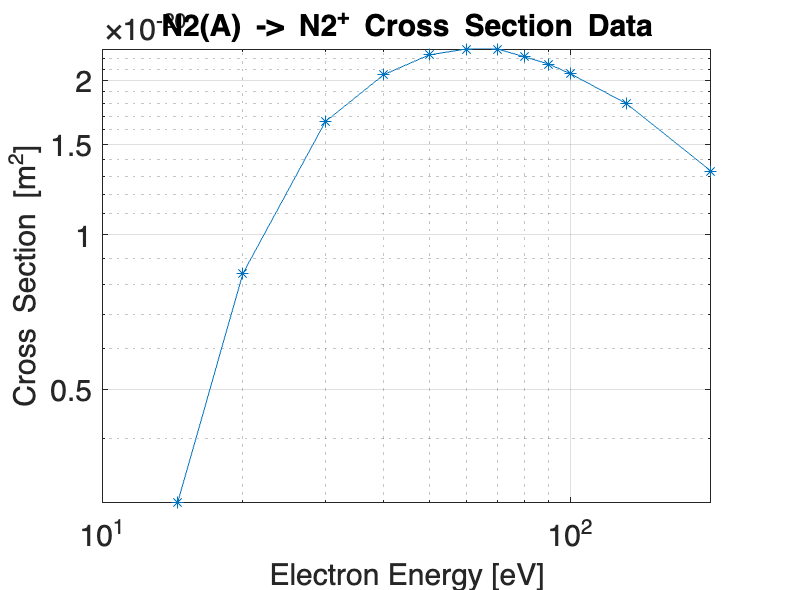


if plotIntermediate
    Plot_CrossSection = figure;
    loglog(reactionCrossSectionalData(:,1),reactionCrossSectionalData(:,2), '-*')
    grid on
    Plot_CrossSection.CurrentAxes.Title.String = strcat([data.(reactionField).chemistry ,' Cross Section Data']);
    Plot_CrossSection.CurrentAxes.XLabel.String = 'Electron Energy [eV]';
    Plot_CrossSection.CurrentAxes.YLabel.String = 'Cross Section [m^2]';
    fontsize(15, "points")
end

## Finding Electron Energy Distribution Function (EEDF)


$$f\left(\epsilon ,T_e \right)=\sqrt{\frac{\epsilon }{\pi }}{2\left(\frac{1}{k_B T_e }\right)}^{\frac{3}{2}} \exp \left(-\frac{\epsilon }{k_B T_e }\right)$$
 

where $k_B$ is Boltzman constant of 8.617E−5 eV⋅K−1 

$T_e$ is electron temperature as a function of time, and $\epsilon$ is electron energy which comes from the cross sectional data. 

### Loading Electron Temerature Evolution

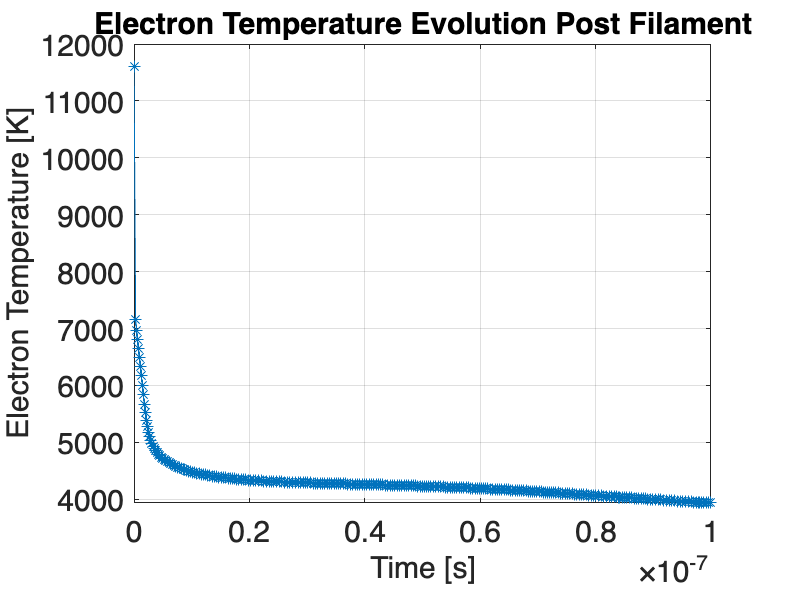

% T_e and time
load ../MASTER_electronTempTimeEvolution.mat
% time is in seconds (first column), T_Te is in Kelvin (second column)
Te_evolution = [time; T_Te]';
clear time T_Te
if plotIntermediate
    Plot_ElectronTemp = figure;
    plot(Te_evolution(:,1), Te_evolution(:,2), '-*')
    Plot_ElectronTemp.CurrentAxes.Title.String = 'Electron Temperature Evolution Post Filament';
    Plot_ElectronTemp.CurrentAxes.XLabel.String = 'Time [s]';
    Plot_ElectronTemp.CurrentAxes.YLabel.String = 'Electron Temperature [K]';
    grid on
    fontsize(15, "points")
end

### Defining EEDF Function

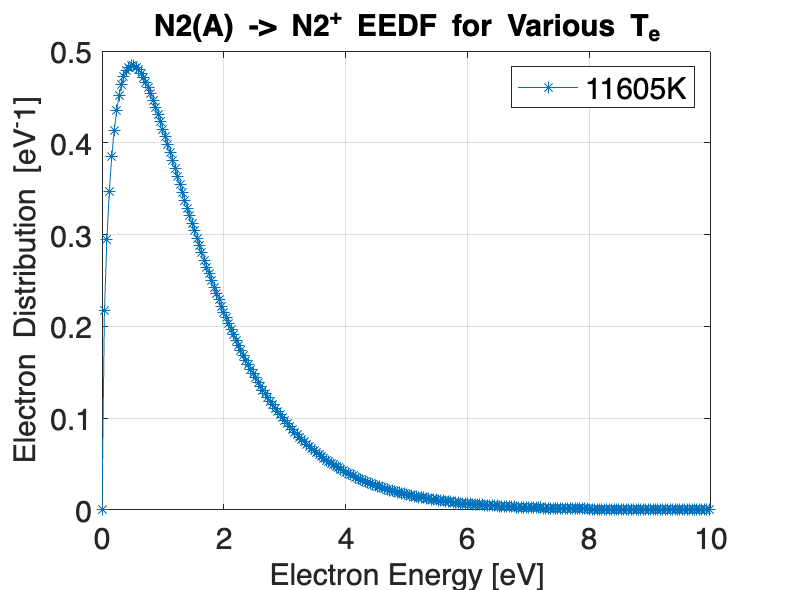

% EEDF function with energy (eV) and Te (K) as input
% Normalized EEDF
% Given
kB = 8.617333262e-5;
eedf = @(epsilon, Te) sqrt(epsilon./pi) .* 2*(1/kB/Te)^(3/2) .* exp(-epsilon/kB/Te);

% Epsilon is electron energy. Let's plot the EEDF function for 0 - 40 eV
epsilon_EEDF = linspace(0, 40, 1000)';

% if we are only plotting on eedf(Te) graph, which incide of the Te
% variable do we want to plot?
singePlotTeValue = 1;
Te = Te_evolution(singePlotTeValue,2);

% the normalized tolerance will check if the integral of the EEDF is this
% far away from a value if 1, indiciating (if true) that is's normalized
normalizedTolerance = 1e-15;
% compute integral of EEDF to check if it's normalized
integralEEDF = integral(@(epsilon) eedf(epsilon,Te), 0, Inf);

if (1-integralEEDF) > normalizedTolerance
    err = (1-integralEEDF)
    error('EEDF is not normalized');
end


normalizedEEDF = eedf(epsilon_EEDF,Te);

if plotIntermediate
    Plot_EEDF = figure;
    temperature = [num2str(floor(Te_evolution(singePlotTeValue,2))), 'K'];
    plot(epsilon_EEDF,normalizedEEDF, '*-', 'DisplayName', temperature);

    if plotMultipleEEDF
        hold on
        for i = [2 5 100]
            temperature = [num2str(floor(Te_evolution(i,2))), 'K'];
            plot(epsilon_EEDF,eedf(epsilon_EEDF,Te_evolution(i,2)), '*-', 'DisplayName',temperature);
        end
        hold off
    end

    legend
    grid on
    Plot_EEDF.CurrentAxes.Title.String = strcat([data.(reactionField).chemistry ' EEDF for Various T_e']);
    Plot_EEDF.CurrentAxes.XLabel.String = 'Electron Energy [eV]';
    Plot_EEDF.CurrentAxes.YLabel.String = 'Electron Distribution [eV^-1]';
    fontsize(15, "points")
    xlim([0 10])
end

## Compute Reaction Rate as Function of Te

$k\left(T_e \right)=\int_0^{\infty } \sigma \left(\epsilon \right)f\left(\epsilon ,T_e \right)v\left(\epsilon \right)d\epsilon$ where $\sigma$ is the cross sectional data that coressponds to electron energy, $\epsilon$, $v\left(\epsilon \right)$ is electron velocity. This is computed from the kinetic energy equation of 

$E=\frac{1}{2}{\textrm{mv}}^2$ but for electrons becomes $\epsilon =\frac{1}{2}m_e v_e^2$ where $m_e$ is electron mass of 9.109E-31 kg. In order to use this equation to solve for $v_e$ $,\;\epsilon$ needs to be in units of J

$v_e =\sqrt{2\frac{\epsilon }{m_e }}$ has units of $\sqrt{\frac{\textrm{eV}}{\textrm{kg}}}$ but eV can be converted to J via $1\textrm{eV}=1\ldotp 60218E-\textrm{19}\;J$ then $\sqrt{\frac{J}{\textrm{kg}}}=\sqrt{\frac{\textrm{Nm}}{\textrm{kg}}}=\sqrt{\textrm{kg}*\frac{m}{s^2 }\;\frac{m}{\textrm{kg}}}=\sqrt{\frac{m^2 }{s^2 }}=\frac{m}{s}$


$$\epsilon \;\left\lbrack \textrm{eV}\right\rbrack *\frac{1\ldotp 602E-19\;\left\lbrack J\right\rbrack }{1\;\left\lbrack \textrm{eV}\right\rbrack }=\epsilon \;\left\lbrack J\right\rbrack$$


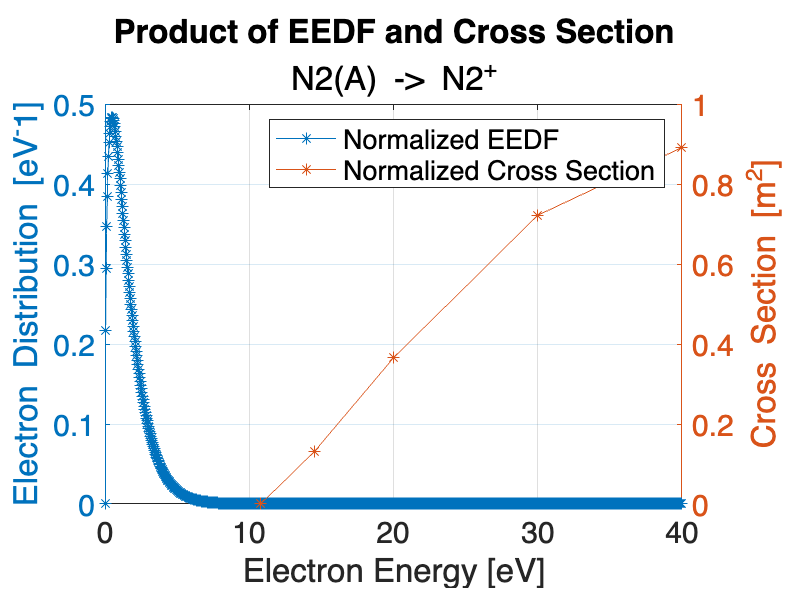

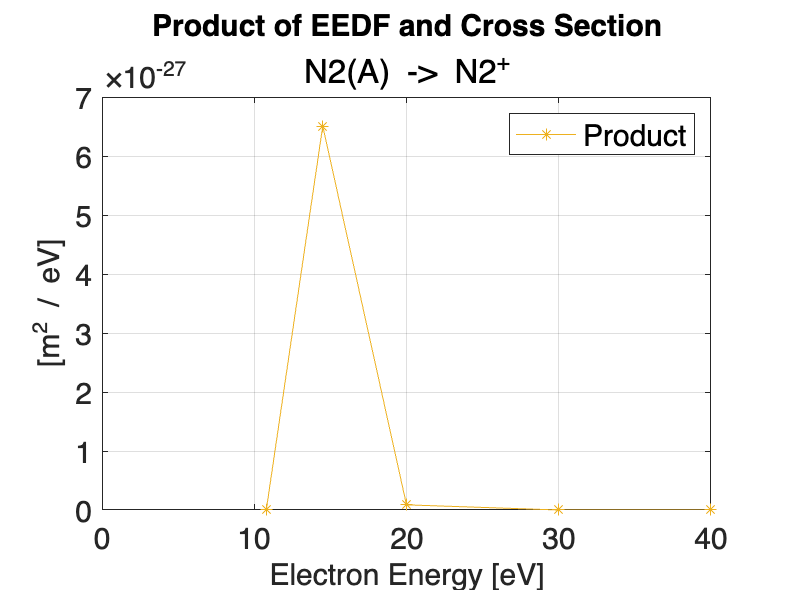

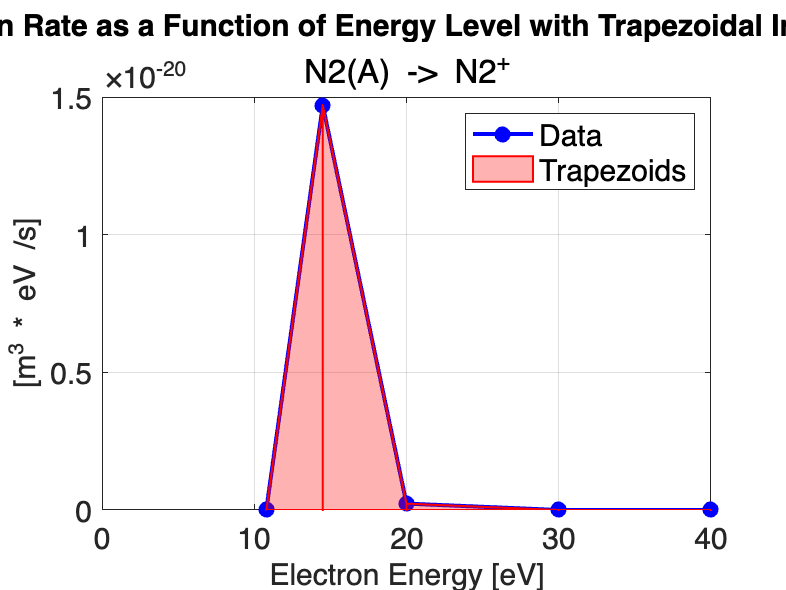

mE = 9.1093837e-31; % kilograms
c = 3e8; % speed of light, m/s
% convert eV to J
eVtoJ = 1.60218e-19;

sigma = reactionCrossSectionalData(:,2);
scaleFactor = 2e19;
% call the function & plot
epsilon_CrossSection = reactionCrossSectionalData(:,1);

% Defining reaction Rate Equatioon
k = @(epsilon, Te) sigma .* eedf(epsilon, Te) .* sqrt(2*epsilon*eVtoJ/mE);

% plotting what's happening inside of k by graphing both EEDF and cross section on same axis
if plotIntermediate
    Plot_EEDF_and_CrossSection = figure;
    yyaxis left
    plot(epsilon_EEDF,normalizedEEDF, '*-')
    hold on
    % mat2gray converts the matrix A to a grayscale image I that contains values in the range 0 (black) to 1 (white).
    plot(epsilon_CrossSection, 0.5*mat2gray(sigma), '-*', 'Color',"#D95319")
    grid on
    xlim([0 40])
    fontsize(15, "points")
    legend('Normalized EEDF','Normalized Cross Section')
    hold off
    title(['Product of EEDF and Cross Section'])
    subtitle(data.(reactionField).chemistry)
    Plot_EEDF_and_CrossSection.CurrentAxes.XLabel.String = 'Electron Energy [eV]';
    Plot_EEDF_and_CrossSection.CurrentAxes.YLabel.String = 'Electron Distribution [eV^-1]';
    yyaxis right
    Plot_EEDF_and_CrossSection.CurrentAxes.YLabel.String = 'Cross Section [m^2]';
    hold off


    Plot_Product = figure;
    plot(epsilon_CrossSection, (sigma.*eedf(epsilon_CrossSection, Te)), '-*', 'Color','#EDB120')
    title('Product of EEDF and Cross Section')
    Plot_Product.CurrentAxes.XLabel.String = 'Electron Energy [eV]';
    Plot_Product.CurrentAxes.YLabel.String = '[m^2 / eV]';
    subtitle(data.(reactionField).chemistry)
    legend('Product')
    xlim([0 40])
    grid on
    fontsize(15, "points")

    % plotting the k function
    figure;
    plot(epsilon_CrossSection, k(epsilon_CrossSection, Te), 'b-o', 'LineWidth', 2, 'MarkerFaceColor', 'b')
    title('Reaction Rate as a Function of Energy Level with Trapezoidal Integration');
    subtitle(data.(reactionField).chemistry)
    ylabel('[m^3 * eV /s]')
    xlabel('Electron Energy [eV]')
    grid on
    xlim([0 40])
    hold on
    fontsize(15, "points")

    x = epsilon_CrossSection;
    y = k(epsilon_CrossSection, Te);
    % Initialize cumulative sum
    cumulative_sum = 0;

    % Plot the trapezoids used in the integration
    for i = 1:length(x)-1
        % Coordinates of the trapezoid corners
        x_trap = [x(i), x(i+1), x(i+1), x(i)];  % x points of the trapezoid
        y_trap = [0, 0, y(i+1), y(i)];          % y points of the trapezoid

        % Compute the area of the trapezoid
        trapezoid_area = (x(i+1) - x(i)) * (y(i+1) + y(i)) / 2;

        % Update cumulative sum
        cumulative_sum = cumulative_sum + trapezoid_area;

        % Fill the trapezoid with transparency
        fill(x_trap, y_trap, 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'r', 'LineWidth', 1);

        % Calculate the position for the text (middle of the trapezoid)
        x_text = (x(i) + x(i+1)) / 2;
        y_text = max(y(i), y(i+1)) / 2;  % Place text midway in y-direction of the trapezoid

        % Display the cumulative sum inside the trapezoid every 10th traps
        if mod(i,10)==0
            text(x_text, y_text, sprintf('%.2e', cumulative_sum), 'FontSize', 10, 'HorizontalAlignment', 'center');
        end
    end


    % Show the plot
    % subtitle(['Te = ', num2str(Te), 'K; Trapz = ', num2str(cumulative_sum)])
    hold off;
    legend('Data', 'Trapezoids');
    fontsize(15, "points")
end

% reactionRateIntegral = trapz(epsilon_CrossSection, k(epsilon_CrossSection, Te));

Rxn_Rate = zeros(1,size(Te_evolution,1))';

for i = 1:size(Te_evolution,1)
    Te = Te_evolution(i,2);
    % Rxn_Rate_N2Ion(i) = sum(k_N2Ion(epsilon, Te, sigma));
    Rxn_Rate(i) = trapz(epsilon_CrossSection, k(epsilon_CrossSection, Te));
end
% transpose to make like rest of variables
fitting_Te = Te_evolution(:,2);

% convert RxnRate from m3/s to cm3/s


$$m^3 *\left(\frac{100\;\textrm{cm}}{1\;m}\right){\;}^3 ={\textrm{cm}}^3$$


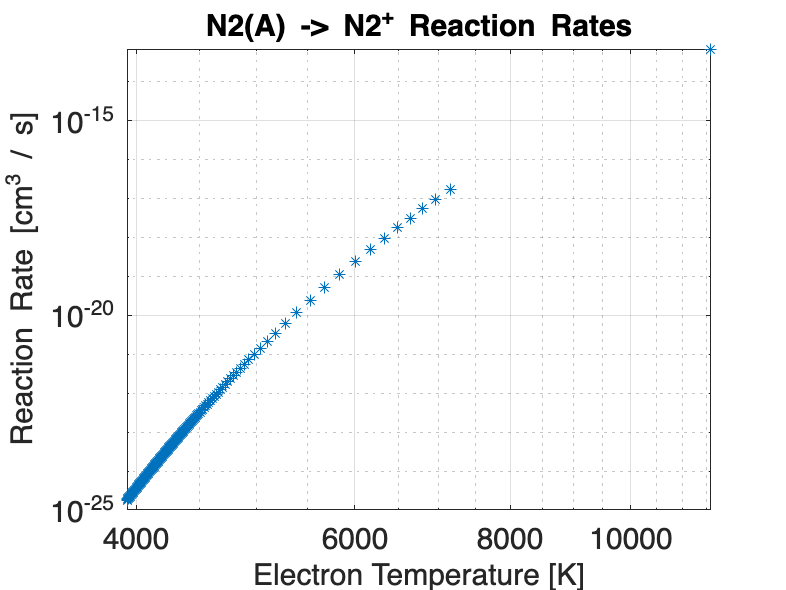

Rxn_Rate = Rxn_Rate .* 100^3;
if plotIntermediate
    Plot_RxnRate = figure;
    loglog(fitting_Te, Rxn_Rate, '*')
    % grid on
    Plot_RxnRate.CurrentAxes.Title.String = strcat([data.(reactionField).chemistry,' Reaction Rates']);
    Plot_RxnRate.CurrentAxes.XLabel.String = 'Electron Temperature [K]';
    Plot_RxnRate.CurrentAxes.YLabel.String = 'Reaction Rate [cm^3 / s]';
    grid on
end
fontsize(15, "points")

## Fit to the Arrhenius Rate

$k\left(T_e \right)=A\;{\textrm{Te}}^n \exp \left(-\frac{E_a }{\textrm{Te}}\right)$ where A and n are rate constants, $E_a$ is the activation energy. 


%
% initialGuess = [A Ea n];

% Define the objective function to minimize
objectiveFunction = @(params) computeSSE(params, fitting_Te, Rxn_Rate);

% Initial guesses for A, Ea, and n
% check if initial conditions are saved in the stucture, and if so, use
% those instead
if isfield(data.(reactionField), 'InitialConditions') && ~overwriteIC
    initialParams = data.(reactionField).InitialConditions;

    if ~silenceOutput
        disp('Loading Initial Conditions from Structure')
        disp(['Initial A: ', num2str(initialParams(1))]);
        disp(['Initial Ea: ',num2str(initialParams(2))]);
        disp(['Initial n: ', num2str(initialParams(3))]);
    end

else
    initialParams = initialGuess;  % [A, Ea, n] adjust these as needed
    if ~silenceOutput
        disp('Loading Initial Conditions from Initial Guess')
        disp(['Initial A: ', num2str(initialParams(1))]);
        disp(['Initial Ea: ',num2str(initialParams(2))]);
        disp(['Initial n: ', num2str(initialParams(3))]);
    end
end

Loading Initial Conditions from Structure


Initial A: 1e-11


Initial Ea: 180000


Initial n: 0.3


% Set optimization options, increasing MaxFunEvals and MaxIter
n = 1e4;
options = optimset('MaxFunEvals', n, 'MaxIter', n, 'Display','off');  % Increase as needed

% Use fminsearch to minimize the SSE
optimizedParams = fminsearch(objectiveFunction, initialParams, options);

% Display the optimized parameters
if ~silenceOutput
    A_opt = optimizedParams(1);
    Ea_opt = optimizedParams(2);
    n_opt = optimizedParams(3);
    disp(['Optimized A: ', num2str(A_opt)]);
    disp(['Optimized Ea: ', num2str(Ea_opt)]);
    disp(['Optimized n: ', num2str(n_opt)]);
end

Optimized A: 1.1061e-12


Optimized Ea: 145909.4566


Optimized n: 1.0476


% Compute and display the final SSE
final_sse = computeSSE(optimizedParams, fitting_Te, Rxn_Rate);


reaction  = data.(reactionField).chemistry;
[fitresult, gof] = ArrheniusFit(fitting_Te, Rxn_Rate, optimizedParams, reaction);

ArrheniusFit is not found in the current folder or on the MATLAB path, but exists in:
    /Users/sethwilson/Library/CloudStorage/OneDrive-Colostate/fs-ns Dual Pulse/Seth's Local Files/ZDPlasKin/BOLSIG Rates
    /Users/sethwilson/Library/Mobile Documents/com~apple~CloudDocs/Graduate School/fs Laser/ZDPlasKin/BOLSIG Rates

Change the MATLAB current folder or add its folder to the MATLAB path.

if ~silenceOutput
    fitresult
    gof
end
fontsize(15, "points")


% tbl = table(fitting_Te, Rxn_Rate);

% beta0 = [3e-12 0.6 180e3];
% % mdl = fitnlm(tbl,modelfun,beta0)
% [beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(fitting_Te, Rxn_Rate,modelfun,beta0);

## Plotting

% % manual fit
A =         1e-9;
Ea =      22900;
n =         -1.33;

modelfun = @(b,x) b(1).*x(:,1).^b(3) .* exp(-b(2)./x(:,1));

Plot_RxnRateComp = figure;
% true data points
semilogy(fitting_Te, Rxn_Rate, '*')
hold on
modelTe = 3000:10:25000;
% plot fminsearch
semilogy(modelTe,modelfun(optimizedParams, modelTe'), '--', 'LineWidth',2)
% plot custom equation
semilogy(modelTe,modelfun([fitresult.A, fitresult.Ea, fitresult.n], modelTe'), '-')
% plot manual conditions
% semilogy(modelTe,modelfun([A Ea n], modelTe'), '-')

Plot_RxnRateComp.CurrentAxes.Title.String = strcat([data.(reactionField).chemistry,' Fit Comparison']);
Plot_RxnRateComp.CurrentAxes.XLabel.String = 'Electron Temperature [K]';
Plot_RxnRateComp.CurrentAxes.YLabel.String = 'Reaction Rate [cm^3 / s]';
Plot_RxnRateComp.CurrentAxes.XAxis.Exponent = 0;

% legend('Data', 'Nonlinear Fitting', 'Custom Nonlinear', 'Manual', 'Location','southeast')

legend('Data', 'Nonlinear Fitting', 'Custom Nonlinear', 'Location','southeast')

% legend('Data', 'Nonlinear Fitting','Location','best')
hold off
fontsize(15, "points")
grid on


## Save Initial Conditions and Final Values to data structure


if saveData
    data.(reactionField).InitialConditions = initialParams;

    if ~saveFMinSearch
        data.(reactionField).A = fitresult.A;
        data.(reactionField).Ea = fitresult.Ea;
        data.(reactionField).n = fitresult.n;
        data.(reactionField).SSE = gof.sse;
    else
        data.(reactionField).A = A_opt;
        data.(reactionField).Ea = Ea_opt;
        data.(reactionField).n = n_opt;
        data.(reactionField).SSE = gof.sse;
    end

    disp(['Final A: ', num2str(fitresult.A)]);
    disp(['Final Ea: ', num2str(fitresult.Ea)]);
    disp(['Final n: ', num2str(fitresult.n)]);
    disp(['Final SSE: ', num2str(final_sse)]);
    save('BOLSIG_Rates_Data',"data")
end


## Creation Reaction Table

% Assume 'data' is the input 1x1 structure with 67 fields.
% Each field has subfields '.chemistry', '.A', '.Ea', and '.n'.

% Get all field names of the structure
fields = fieldnames(data);

% Preallocate cell arrays for the table columns
fieldNames = cell(length(fields), 1);
chemistryValues = cell(length(fields), 1);
A_values = zeros(length(fields), 1);  % Assuming numeric values for A
Ea_values = zeros(length(fields), 1); % Assuming numeric values for Ea
n_values = zeros(length(fields), 1);  % Assuming numeric values for n

% Loop over all fields and extract the relevant values
for i = 1:length(fields)
    fieldName = fields{i};
    fieldNames{i} = fieldName;  % Store the field name
    chemistryValues{i} = data.(fieldName).chemistry;  % Store the chemistry value
    A_values(i) = data.(fieldName).A;  % Store the A value
    Ea_values(i) = data.(fieldName).Ea;  % Store the Ea value
    n_values(i) = data.(fieldName).n;  % Store the n value
end

% Create a table with five columns: 'ReactionName', 'Chemistry', 'A', 'Ea', and 'n'
reactionTable = table(fieldNames, chemistryValues, A_values, Ea_values, n_values, ...
    'VariableNames', {'ReactionName', 'Chemistry', 'A', 'Ea', 'n'});

% Display the table
% disp(reactionTable);
save("reactionTable",'reactionTable')

%     proceed = input('Press Enter to proceed, or any other key to exit: ', 's');
%     if isempty(proceed)  % If Enter is pressed (empty input)
%         % disp(['Continuing the loop, iteration: ', num2str(i)]);
%         % % Your code for this iteration
%         delete(Plot_RxnRateComp)
%         drawnow
%     else
%         % disp('Exiting the loop.');
%         break;
%     end
%
% end
disp(reactionTable);

Function to compute SSE

function sse = computeSSE(params, fitting_Te, Rxn_Rate)
A = params(1);
Ea = params(2);
n = params(3);

% Arrhenius equation
k_fit = A .* fitting_Te.^n .* exp(-Ea ./ fitting_Te);

% Calculate the sum of squares due to error (SSE)
sse = sum((Rxn_Rate - k_fit).^2);
end